# Demodulate Audio 

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports the watermarked audio file.

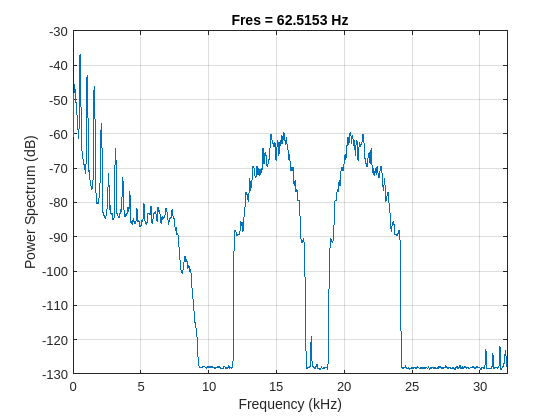

[flute, fs] = audioread("./data/MarkedFlute.wav");
fc = 18000;
pspectrum(flute, fs)

This code imports and processes the birds file, so that you can compare it to the demodulated watermark.

[birds, fsb] = audioread("./data/bird-call-in-spring.mp3");
birds = mean(birds, 2);
birds = resample(birds, 640, 441);
birds = birds(1:numel(flute));
birds = bandpass(birds, [1000 6000], fs);

## Task 1

If you wanted to prove ownership of the audio file, you could get the watermark and demodulate it.

The watermarked audio has been imported into the variables `flute` and `fs`.

flutefilt = highpass(flute, fc, fs);

## Task 2

You can demodulate the signal using the same inputs that you used with the `modulate` function.

`y` `=` `demod``(``sig``,``fc``,``fs``)`

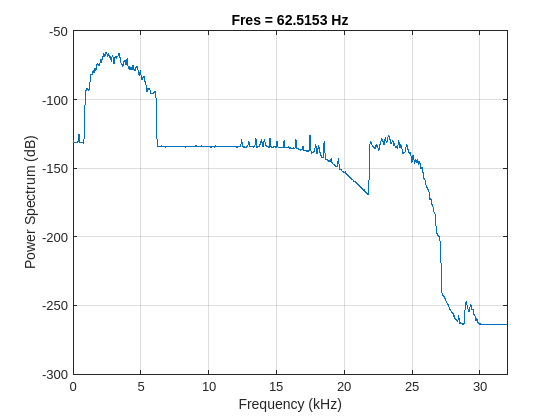

wm = demod(flutefilt, fc, fs);
pspectrum(wm, fs);